%% AUTOENCODER SU VOLTI (MLX)
% Pipeline SVD_BC → Autoencoder sui coefficienti principali
clear; clc; close all;
rng(0);

%% 0) IMPOSTAZIONE AMBIENTE & CARTELLA RISULTATI
projectRoot = '/Users/…/ProgettoMetodi';
addpath(genpath(projectRoot));   
this_folder  = pwd;
results_path = fullfile(this_folder,'results');
if ~exist(results_path,'dir')
    mkdir(results_path);
    fprintf('>>> Creo la cartella results\n');
end

%% 1) PARAMETRI SVD
tol   = 1e-4;
maxit = 1000;
energy_threshold = 0.95;   % mantieni il 95% dell’energia

%% 2) CARICAMENTO DATASET & MEAN FACE
fprintf('>>> Caricamento dataset ORL...\n');  t_start = tic;

>>> Caricamento dataset ORL...


load('dataset/volti_dataset_Yale.mat');  % A (m×n), labels (ignored)
A = double(A)/255;
fprintf('   fatto in %.2f s\n', toc(t_start));

   fatto in 0.07 s



[m, n] = size(A);
img_h = 112;  img_w = 92;

fprintf('>>> Calcolo volto medio...\n');  t_start = tic;

>>> Calcolo volto medio...


mean_face = mean(A,2);
save(fullfile(results_path,'mean_face.mat'),'mean_face');
fprintf('   ok in %.2f s\n', toc(t_start));

   ok in 0.02 s



fprintf('>>> Centratura dati...\n');  t_start = tic;

>>> Centratura dati...


A_centered = A - mean_face;
fprintf('   ok in %.2f s\n', toc(t_start));

   ok in 0.00 s



%% 3) SVD_BC su dati centrati
fprintf('>>> Lancio svd_BC (tol=%.1e, maxit=%d)...\n', tol, maxit);

>>> Lancio svd_BC (tol=1.0e-04, maxit=1000)...


t_start = tic;
[U, S, V] = svd_BC(A_centered, tol, maxit);

   [svd_BC] costruisco ATA...
   [svd_BC] chiamo qr_eig su 165x165 (tol=1.0e-04,maxit=1000)...
         [qr_eig] deflazione k=165 ... 

iter=1001 time=5.08 s
         [qr_eig] deflazione k=164 ... 

iter=1001 time=4.07 s
         [qr_eig] deflazione k=163 ... 

iter=1001 time=3.37 s
         [qr_eig] deflazione k=162 ... iter=338 time=0.94 s
         [qr_eig] deflazione k=161 ... 

iter=1001 time=3.22 s
         [qr_eig] deflazione k=160 ... iter=309 time=1.08 s
         [qr_eig] deflazione k=159 ... 

iter=1001 time=2.97 s
         [qr_eig] deflazione k=158 ... 

iter=1001 time=2.89 s
         [qr_eig] deflazione k=157 ... 

iter=1001 time=2.80 s
         [qr_eig] deflazione k=156 ... iter=765 time=2.69 s
         [qr_eig] deflazione k=155 ... 

iter=1001 time=3.21 s
         [qr_eig] deflazione k=154 ... 

iter=1001 time=3.68 s
         [qr_eig] deflazione k=153 ... 

iter=1001 time=2.86 s
         [qr_eig] deflazione k=152 ... 

iter=1001 time=2.87 s
         [qr_eig] deflazione k=151 ... 

iter=1001 time=2.81 s
         [qr_eig] deflazione k=150 ... 

iter=1001 time=2.82 s
         [qr_eig] deflazione k=149 ... 

iter=1001 time=2.70 s
         [qr_eig] deflazione k=148 ... 

iter=1001 time=2.04 s
         [qr_eig] deflazione k=147 ... 

iter=1001 time=2.23 s
         [qr_eig] deflazione k=146 ... 

iter=1001 time=1.75 s
         [qr_eig] deflazione k=145 ... 

iter=1001 time=1.96 s
         [qr_eig] deflazione k=144 ... 

iter=1001 time=1.90 s
         [qr_eig] deflazione k=143 ... 

iter=1001 time=1.86 s
         [qr_eig] deflazione k=142 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=141 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=140 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=139 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=138 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=137 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=136 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=135 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=134 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=133 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=132 ... 

iter=1001 time=0.74 s
         [qr_eig] deflazione k=131 ... 

iter=1001 time=0.71 s
         [qr_eig] deflazione k=130 ... 

iter=1001 time=0.69 s
         [qr_eig] deflazione k=129 ... 

iter=1001 time=0.69 s
         [qr_eig] deflazione k=128 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=127 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=126 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=125 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=124 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=123 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=122 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=121 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=120 ... iter=90 time=0.05 s
         [qr_eig] deflazione k=119 ... 

iter=1001 time=0.59 s
         [qr_eig] deflazione k=118 ... 

iter=1001 time=0.64 s
         [qr_eig] deflazione k=117 ... 

iter=1001 time=0.74 s
         [qr_eig] deflazione k=116 ... 

iter=1001 time=0.56 s
         [qr_eig] deflazione k=115 ... 

iter=1001 time=0.56 s
         [qr_eig] deflazione k=114 ... iter=2 time=0.00 s
         [qr_eig] deflazione k=113 ... iter=514 time=0.28 s
         [qr_eig] deflazione k=112 ... 

iter=1001 time=0.52 s
         [qr_eig] deflazione k=111 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=110 ... 

iter=1001 time=0.51 s
         [qr_eig] deflazione k=109 ... 

iter=1001 time=0.50 s
         [qr_eig] deflazione k=108 ... 

iter=1001 time=0.59 s
         [qr_eig] deflazione k=107 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=106 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=105 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=104 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=103 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=102 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=101 ... iter=989 time=0.51 s
         [qr_eig] deflazione k=100 ... 

iter=1001 time=0.48 s
         [qr_eig] deflazione k=99 ... 

iter=1001 time=0.51 s
         [qr_eig] deflazione k=98 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=97 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=96 ... 

iter=1001 time=0.43 s
         [qr_eig] deflazione k=95 ... 

iter=1001 time=0.41 s
         [qr_eig] deflazione k=94 ... 

iter=1001 time=0.45 s
         [qr_eig] deflazione k=93 ... 

iter=1001 time=0.45 s
         [qr_eig] deflazione k=92 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=91 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=90 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=89 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=88 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=87 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=86 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=85 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=84 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=83 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=82 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=81 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=80 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=79 ... 

iter=1001 time=0.33 s
         [qr_eig] deflazione k=78 ... 

iter=1001 time=0.30 s
         [qr_eig] deflazione k=77 ... iter=344 time=0.10 s
         [qr_eig] deflazione k=76 ... 

iter=1001 time=0.27 s
         [qr_eig] deflazione k=75 ... 

iter=1001 time=0.27 s
         [qr_eig] deflazione k=74 ... 

iter=1001 time=0.26 s
         [qr_eig] deflazione k=73 ... 

iter=1001 time=0.26 s
         [qr_eig] deflazione k=72 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=71 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=70 ... iter=906 time=0.22 s
         [qr_eig] deflazione k=69 ... 

iter=1001 time=0.24 s
         [qr_eig] deflazione k=68 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=67 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=66 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=65 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=64 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=63 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=62 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=61 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=60 ... 

iter=1001 time=0.20 s
         [qr_eig] deflazione k=59 ... 

iter=1001 time=0.20 s
         [qr_eig] deflazione k=58 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=57 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=56 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=55 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=54 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=53 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=52 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=51 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=50 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=49 ... iter=2 time=0.00 s
         [qr_eig] deflazione k=48 ... 

iter=1001 time=0.15 s
         [qr_eig] deflazione k=47 ... 

iter=1001 time=0.14 s
         [qr_eig] deflazione k=46 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=45 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=44 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=43 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=42 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=41 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=40 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=39 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=38 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=37 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=36 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=35 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=34 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=33 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=32 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=31 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=30 ... iter=0 time=0.00 s
         

fprintf('   completata in %.2f s\n', toc(t_start));

   completata in 76.63 s


save(fullfile(results_path,'svd_data.mat'),'U','S','V');

%% 4) Selezione k tramite energia cumulata
eigvals = diag(S);
energy  = cumsum(eigvals)/sum(eigvals);
k       = find(energy>energy_threshold,1);
fprintf('>>> Trovati k = %d componenti (%.1f%% energia)\n', k, 100*energy(k));

>>> Trovati k = 161 componenti (95.4% energia)



%% 5) Calcolo e normalizzazione proiezioni [k×n]
P       = U(:,1:k)' * (A - mean_face);   % [k×n]
mu_P    = mean(P,2);
sigma_P = std(P,0,2) + eps;
P_norm  = (P - mu_P) ./ sigma_P;         % [k×n]
X_all   = P_norm';                       % [n×k]

%% 6) SPLIT TRAIN/TEST per l’AE (80/20)
perm       = randperm(n);
n_train    = round(0.8 * n);
train_idx  = perm(1:n_train);
test_idx   = perm(n_train+1:end);
X_train    = X_all(train_idx, :);        % [n_train×k]
X_test     = X_all(test_idx,  :);        % [n_test ×k]
orig_idx_test = test_idx;                % per ricostruzioni pixel

%% 7) Parametri Autoencoder
epochs        = 50;
learning_rate = 0.01;
bottleneck    = 40;   % dimensione del codice

%% 8) Training Autoencoder
fprintf('>>> Training autoencoder su coefficienti PCA (bottleneck = %d)...\n', bottleneck);

>>> Training autoencoder su coefficienti PCA (bottleneck = 40)...


t_start = tic;
[W_enc,b_enc,W_dec,b_dec,loss_history,test_loss_history] = ...
    autoencoder_train_2(X_train, X_test, mean_face, bottleneck, epochs, learning_rate);

[AE] Epoca  10/ 50: Train MSE=0.75325, Test MSE=0.85476
[AE] Epoca  20/ 50: Train MSE=0.51428, Test MSE=0.58957
[AE] Epoca  30/ 50: Train MSE=0.37983, Test MSE=0.44505
[AE] Epoca  40/ 50: Train MSE=0.30818, Test MSE=0.37349
[AE] Epoca  50/ 50: Train MSE=0.25937, Test MSE=0.32349


fprintf('   Fine training in %.2f s\n', toc(t_start));

   Fine training in 0.14 s


save(fullfile(results_path,'ae_weights.mat'),'W_enc','b_enc','W_dec','b_dec','loss_history');

%% 9) VALUTAZIONE SUL TEST SET
n_test     = numel(test_idx);
mse_pixel  = zeros(n_test,1);
for i = 1:n_test
    idx = orig_idx_test(i);
    x_pca_norm    = X_all(idx, :)';                     % [k×1]
    h             = max(0, W_enc * x_pca_norm + b_enc);
    x_hat         = W_dec * h + b_dec;                  % [k×1]
    x_hat_denorm  = x_hat .* sigma_P + mu_P;            % [k×1]
    x_rec         = U(:,1:k) * x_hat_denorm + mean_face;% [m×1]
    x_orig        = A(:, idx);                          % [m×1]
    err           = x_orig - x_rec;
    mse_pixel(i)  = mean(err.^2);
end

mean_mse = mean(mse_pixel);
fprintf('\n>>> RISULTATI TEST SET:\n');


>>> RISULTATI TEST SET:


fprintf('    MSE medio sul test set: %.6f\n', mean_mse);

    MSE medio sul test set: 0.000172


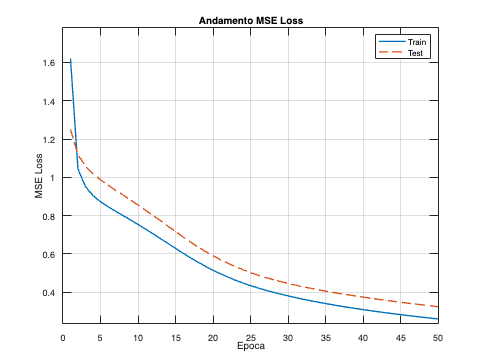


%% 7) PLOT DELL’ANDAMENTO DELLA MSE LOSS
figure('Name','AE: Train vs Test MSE','NumberTitle','off');
plot(1:epochs, loss_history,      '-','LineWidth',1.5); hold on;
plot(1:epochs, test_loss_history, '--','LineWidth',1.5);
xlabel('Epoca'); ylabel('MSE Loss');
legend('Train','Test','Location','northeast');
title('Andamento MSE Loss');
grid on;
% regola i limiti per rendere visibile la test loss orizzontale
ymin = min([loss_history, test_loss_history]) * 0.9;
ymax = max(loss_history) * 1.1;
ylim([ymin, ymax]);

saveas(gcf, fullfile(results_path,'ae_loss_trend.png'));


fprintf('>>> Fine script (totale %.2f s)\n', toc);

>>> Fine script (totale 5211.22 s)
